Definizione del **numeratore** e del **denominatore** della **FdT**.

num = -1;
den = [1 1];

sys = tf(num,den)


sys =
 
   -1
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans = -1

Tracciamento del **diagramma di Bode**.

- In questo si ha un guadagno negativo.

- Tale guadagno comporta un termine costante di fase pari a +180°che va a sommarsi all’andamento dovuto al termine: 1/(𝑠+1).

- **Notare:** che ciò si discosta dalle regole per il tracciamento manuale dei diagrammi di Bode che, invece, per convezione, prevedono un termine pari a −180°in caso di guadagno negativo!

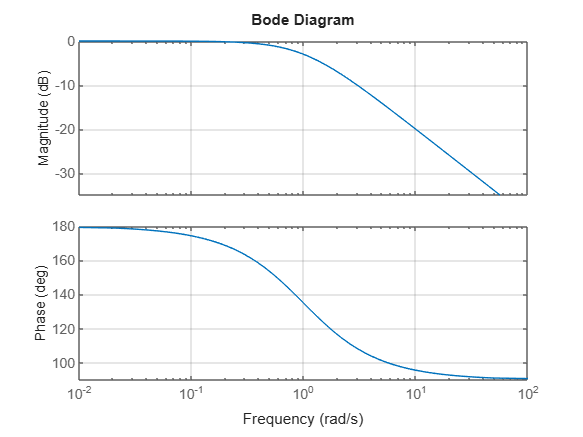

bode(sys);
grid on

Calcolo di** modulo** e** fase** per diversi valori di **w.**

[mag,phase,wout] = bode(sys);